# Homework 1

# Francesco Roncolato - 2032442

## Parte 1

### 1. Caricare un'immagine a livelli di grigio oppure a colori, ma in tal caso bisogna estrarne la componente di luminanza, che può essere approssimata come media delle componenti RGB. 

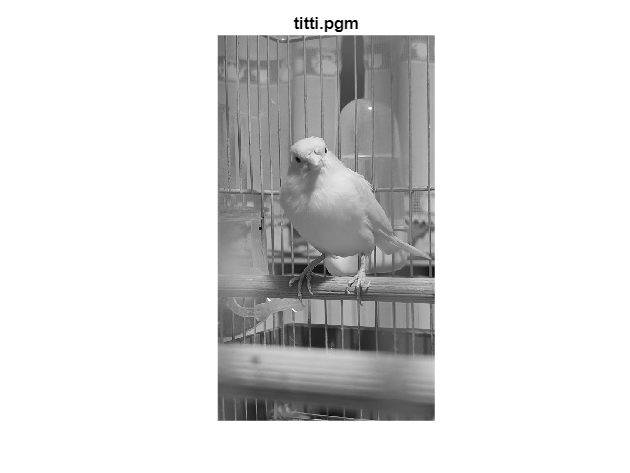

close all; clear variables;
imageName = "tittiColored";
fileName = sprintf('%s.pgm',imageName); % carica l'immagine
imgMatrix = imread(fileName);
[row, col, channels] = size(imgMatrix);
if channels==1 % l'immagine è già in scala di grigi
    f = imgMatrix;
else
    f = rgb2gray(imgMatrix); % estrae la componente di luminanza
    imageName = erase(imageName, 'Colored');
    fileName = sprintf('%s.pgm',imageName);
    imwrite(f, fileName);    % genera l'immagine in scala di grigi
end
nPixel = numel(f); % = row*col
figure; imagesc(f); colormap(gray); axis image; axis off; title(fileName);

Per utilizzare un'immagine a colori, la si chiami con il suo nome seguito da 'Colored'. Viene poi creato il file in sfumature di grigio con il nome senza l'indicazione 'Colored'.

Nel caso in cui venga caricata un'immagine con i tre canali RGB, viene invocata la funzione rgb2gray che fa una media pesata per ogni pixel in modo da ottenere la componente di luminanza. Il calcolo eseguito dalla funzione è


$$gra\textrm{yPixel}=0.2989\ast R+0.5870\ast G+0.1140\ast B$$


#### 2.1 Sia f(n, m) l’immagine a livelli di grigio: stimarne l'entropia esprimendola in bit per pixel

tmp = transpose(f);
rasterScan = tmp(:); % legge i pixel dell'immagine riga per riga
HX = entropy(rasterScan); % funzione definita in fondo al file
fprintf('L''entropia dell''immagine %s è HX = %5.4f bpp\n', imageName, HX);

L'entropia dell'immagine titti è HX = 7.1834 bpp


fprintf('Il rapporto di compressione ottenibile è di %5.4f\n', 8/HX);

Il rapporto di compressione ottenibile è di 1.1137


### 3. Utilizzare un’applicazione come zip in Windows oppure gzip in Linux e calcolare il bitrate risultante (dimensione del file in bit diviso numero di pixel)

cmd = sprintf('zip %s %s.pgm', imageName, imageName);
system(cmd); % invia il comando al SO per l'esecuzione

updating: titti.pgm (164 bytes security) (deflated 35%) 


info=dir(sprintf('%s.zip', imageName));
nBytes = info.bytes; % recupera la dimensione del file ZIP
zip_bpp = nBytes*8/nPixel; % dimensione espressa in bpp
fprintf('Il file %s ha un tasso di codifica %5.4f bpp\n', info.name, zip_bpp);

Il file titti.zip ha un tasso di codifica 5.2428 bpp


### 4. Confrontare l'entropia ottenuta al punto 1 e il tasso ottenuto al punto 3. Discutere il risultato

La compressione eseguita dai software *zip sfrutta la codifica a dizionario cioè cerca pattern di simboli ricorrenti per riempire delle tabelle. Vengono quindi codificati insieme dei gruppi di pixel. Così facendo si può riformulare il teorema di Shannon dividendo tutti i membri per la lunghezza dei gruppi di simboli


$$H(X)\leq\mathcal{L}^*<H(x)+1$$



$$\[ \frac{H(X^K)}{K}\leq\frac{\mathcal{L}^*}{K}=\mathcal{L}^*_S<\frac{H(X^K)}{K}+\frac{1}{K} \]$$
 

Questo significa che all'aumentare della lunghezza $K$ dei simboli, la lunghezza media ottima in bit per simbolo $\mathcal{L}^*_S$ si avvicina sempre di più al tasso entropico $\mathcal{H}$, secondo il teorema dei due carabinieri.

In altre parole, la lunghezza media delle parole di codice sarà sempre (anche nel file $.zip$) maggiore o uguale dell'entropia dell'immagine ma aumentando la lunghezza delle parole di codice si può raggiungere una codifica sempre migliore in termini di bit per pixel. Per questo in generale $zip\_bpp<HX$. Il risultato dipende molto dall'immagine che si considera (si veda il punto 8).

### 5. Effettuare la codifica predittiva “semplice”

####     5.1. L’immagine è rappresentata, dopo una scansione riga per riga (raster scan), su un vettore x 

tmp = transpose(f);
rasterScan = tmp(:);

####     5.2. La predizione di x(n) è x(n − 1), tranne per il primo pixel per il quale la predizione è 128

Quindi la predizione è data da un array dove il primo elemento è 128 e i restanti sono tutti quelli dell'immagine meno l'ultimo.

simPred = [128; double(rasterScan(1:end-1))];

####     5.3. L’errore di predizione è y(n) = x(n) − x(n − 1), tranne per il primo pixel per il quale y(0) = x(0) − 128 (cioè y(n)=x(n)-pred(n))

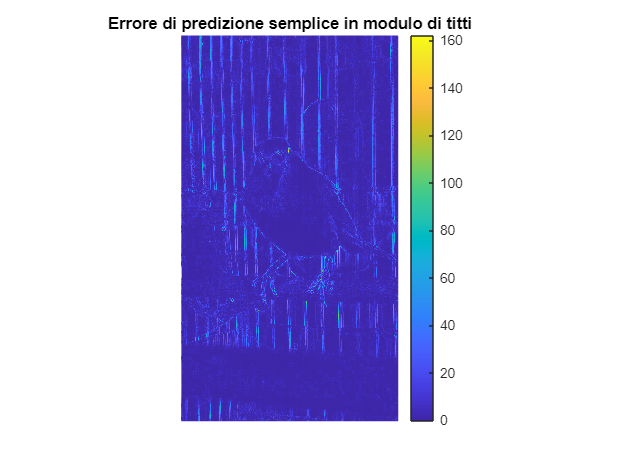

simPredErr = double(rasterScan)-simPred;
figure; imagesc(transpose(reshape(abs(simPredErr),col,row))); axis image; axis off; colorbar; title(sprintf('Errore di predizione semplice in modulo di %s', imageName));
saveas(gcf, sprintf('%sSimplePredErr.png', imageName));

### 6. Stimare l'entropia dell'errore di predizione y

simHY = entropy(simPredErr);
fprintf('L''entropia dell''errore di predizione per %s è HY = %5.4f bpp\n', imageName, simHY);

L'entropia dell'errore di predizione per titti è HY = 4.3854 bpp


fprintf('Il rapporto di compressione ottenibile è di %5.4f\n', 8/simHY);

Il rapporto di compressione ottenibile è di 1.8242


Possiamo inoltre mostrare gli istogrammi per visualizzare la sparsità dell'immagine e dell'errore di predizione

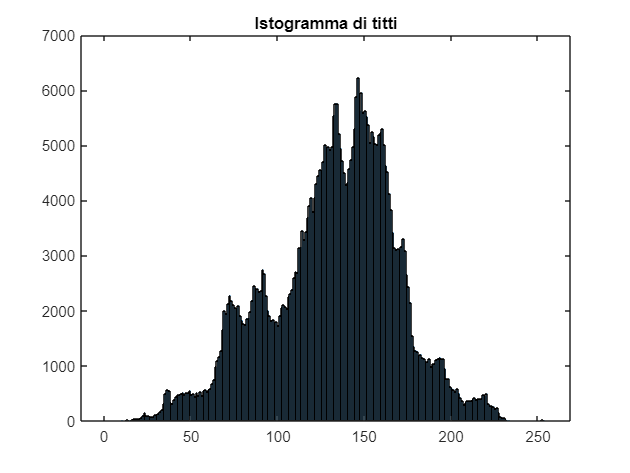

histogram(f,0:256); title(sprintf('Istogramma di %s', imageName));
saveas(gcf, sprintf('%sHist.png', imageName));

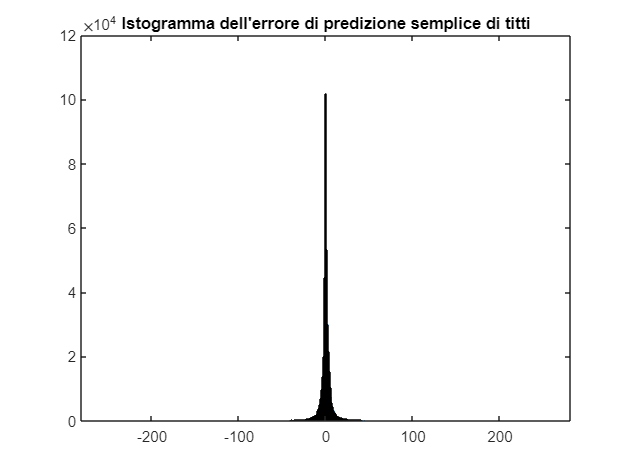

histogram(simPredErr, -255:256); title(sprintf('Istogramma dell''errore di predizione semplice di %s', imageName));
saveas(gcf, sprintf('%sSimplePredHist.png', imageName));

Più è stretto l'istogramma dell'errore, minore sarà la sua entropia e quindi anche il limite di compressione dell'errore di predizione. Se inoltre l'istogramma resta concentrato attorno allo 0 allora la codifica Exp Golomb si rivelerà efficiente.

### 7. Valutare il *numero di bit necessari* per codificare l’errore di predizione y con la codifica *Exp Golomb con segno*, dedurne il bitrate di codifica e confrontare tale valore con quello ottenuto ai punti 1, 3 e 5

Si prende il valore dell'errore per ciascun pixel e lo si codifica con Exp Golomb. Per ogni parola codificata si somma il numero di bit che occupa e infine si divide per fare la media trovando così il tasso in bit per pixel (bpp). La codifica vera e propria è data dalla concatenazione delle codeword.

bitCount = 0;
for index = 1:numel(simPredErr)
    symbol = simPredErr(index);
    codeword = expGolombSigned(double(symbol));
    bitCount = bitCount + numel(codeword);
end
simEG_bpp = bitCount/nPixel;
fprintf('Tasso di codifica S-EG su errore di predizione per %s: %5.4f bpp\n', imageName, simEG_bpp);

Tasso di codifica S-EG su errore di predizione per titti: 4.7837 bpp


La codifica lossless predittiva consiste nel formulare una predizione del simbolo i-esimo sulla base dei simboli precedenti. Se questa predizione è "buona" allora l'errore di predizione sarà piccolo e quindi anche con entropia piccola e in generale minore di quella della sorgente: $H(Y)<H(X)
$. Si può quindi pensare di codificare l'errore di predizione al posto dei simboli di $X$. La codifica, secondo il teorema di Shannon, avrà $H(Y)\leq\mathcal{L}^*_S\leq EG(Y)$. 

È necessario che la predizione si basi solamente sui simboli precedenti perché altrimenti sarebbe impossibile decodificare l'immagine. Il decodificatore può partire dal primo pixel, supporre che il suo valore sia 128 e sommare l'errore per ottenere il valore corretto. Una volta noto il valore corretto del primo pixel si somma a questo l'errore del secondo pixel, e via così.

Se la predizione è buona, l'errore è formato da valori piccoli e quindi diventa vantaggioso utilizzare una codifica come Exp Golomb, che assegna meno bit agli interi con modulo minore.

La predizione che si è fatta al punto 5 consiste nell'ipotizzare che ogni pixel sia uguale al suo precedente. Questo può portare ad un "effetto di bordo" che consiste in un errore diverso, in ogni riga, tra il primo e gli altri pixel. Questo è dovuto al fatto che il pixel "precedente" al primo di una riga è l'ultimo della riga precedente, che si trova al lato opposto dell'immagine e che quindi potrebbe facilmente essere diverso, rendendo imprecisa la predizione. 

Si noti che per trovare il pixel "precedente" si è trasposta e linearizzata l'immagine nell'array rasterScan in modo da avere una lista che itera i pixel dal primo in alto a sinistra, procedendo verso destra e andando a capo alla fine di una riga. Questa operazione risente fortemente dell'orientamento dell'immagine. Se l'immagine è composta perlopiù da striscie verticali si avranno continui cambi di colore e quindi l'errore di predizione sarà grande. Quando muovendosi da sinistra a destra i colori dei pixel cambiano poco (o non cambiano affatto), la predizione è buona e di conseguenza l'errore di predizione piccolo. La predizione così fatta premia quindi le immagini composte da linee orizzontali.

Il cambio di paradigma (codifica dell'errore di predizione in opposizione alla codifica standard dei simboli con dizionario) e il conseguente abbassamento dell'entropia, permette che la codifica predittiva semplice sia più efficace di quella messa in opera dal software zip. Nella quasi totalità delle immagini testate si è infatti trovata un'entropia dell'errore di predizione minore dell'entropia dell'immagine di partenza e minore del tasso di codifica del programma zip. In base poi alle caratteristiche dell'immagine si è rilevata più o meno efficace la codifica Exp Golomb per l'errore.

### 8. Ripetere gli esperimenti per più immagini e riportare i risultati. Commentare quanto trovato

Oltre alle immagini proposte, ho generato e testato la codifica sulle immagini (256x256) vStripes.pgm, hStripes.pgm, vShade.pgm, hShade.pgm e noise.pgm (rispettivamente composte da linee verticali, linee orizzontali, sfumatura verticale, sfumatura orizzontale e pixel generati randomicamente). 

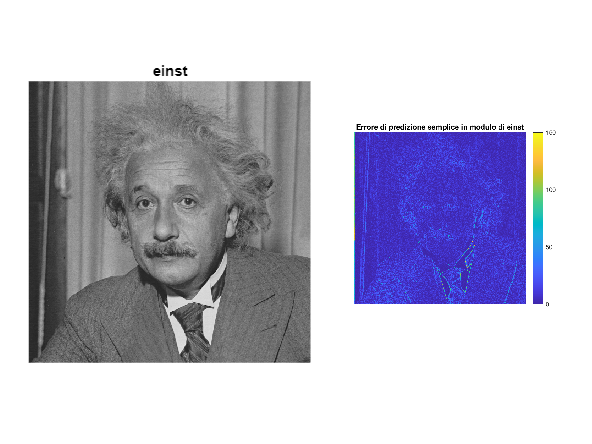

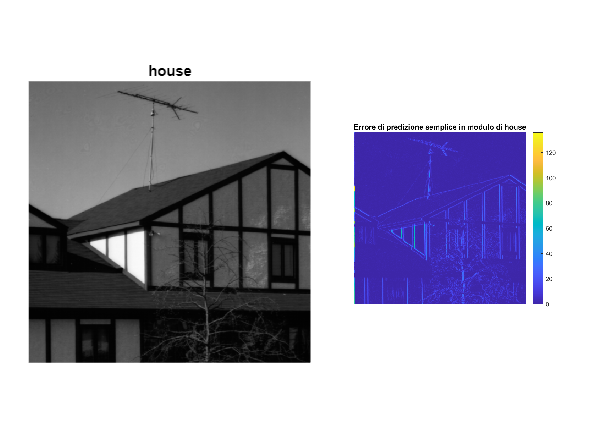

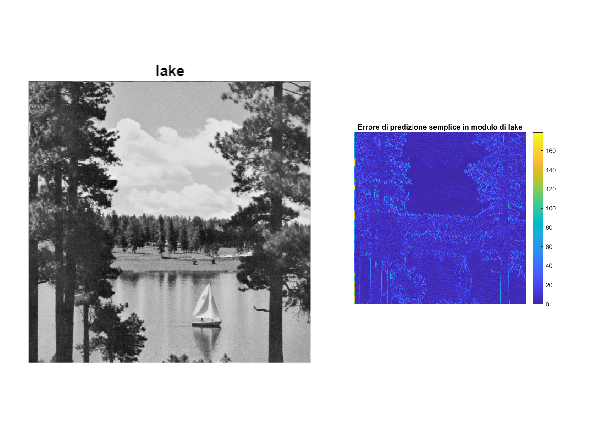

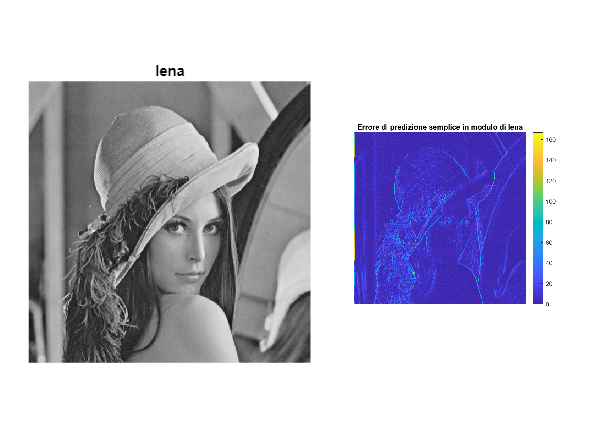

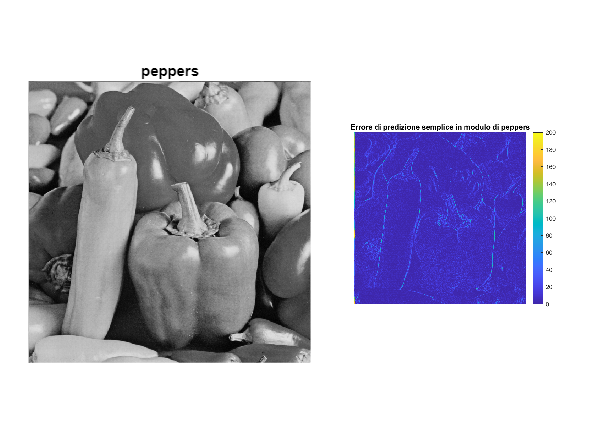

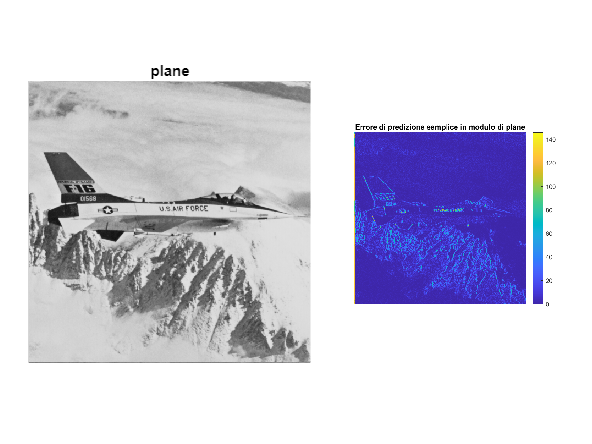

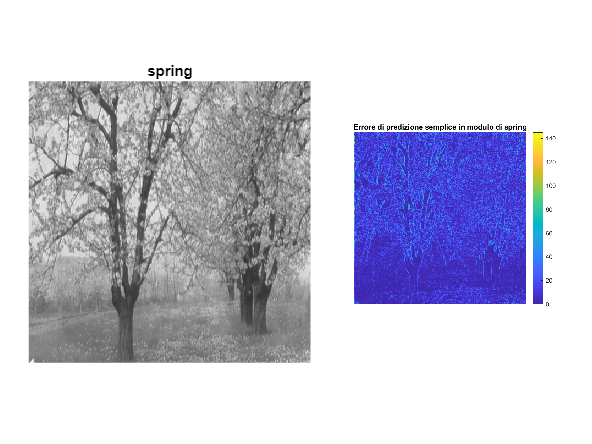

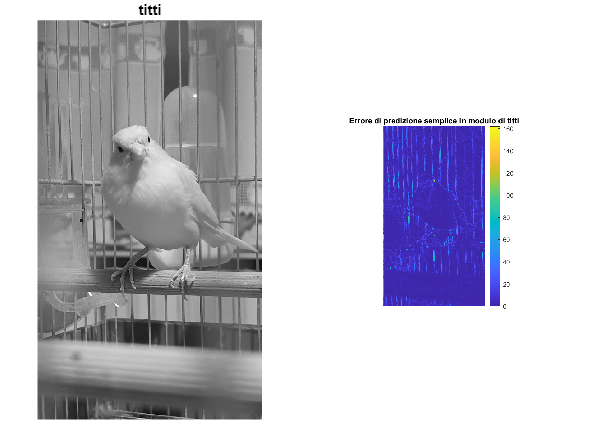

fileList = {'einst', 'house', 'lake', 'lena', 'peppers', 'plane', 'spring', 'titti', 'vStripes', 'hStripes', 'vShade', 'hShade', 'noise'};
for i=1:numel(fileList)
    figure; tiledlayout(1,2,"TileSpacing", 'none', "Padding", 'none');
    nexttile; imshow(imread(sprintf("%s.pgm", fileList{i}))); title(fileList{i});
    nexttile; imshow(imread(sprintf("%sSimplePredErr.png", fileList{i})));
end

Dati raccolti

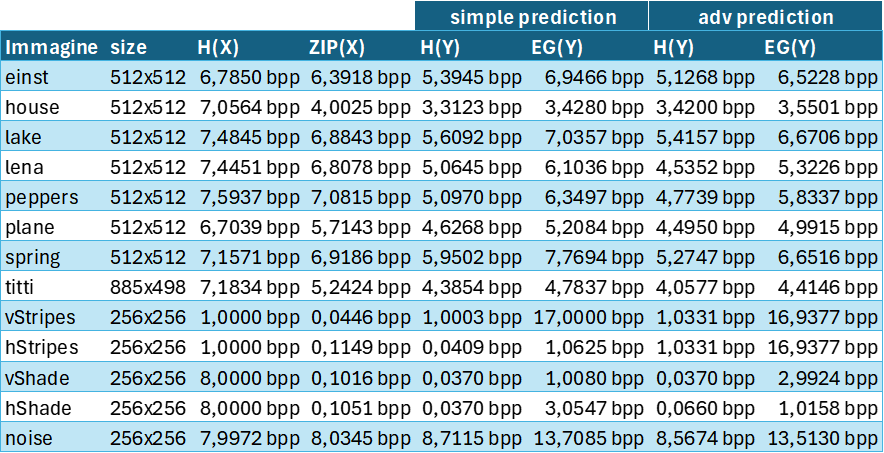

Le immagini reali hanno un'entropia piuttosto alta e zip non riesce a comprimere di molto in quanto non c'è grande regolarità. L'immagine dove la codifica predittiva semplice funziona meglio è 'house' in quanto il cielo varia molto gradualmente verso il basso e orizzontalmente presenta pixel con colore pressoché costante. Si noti che nel caso di 'house' anche zip porta ad un tasso di compressione buono. In 'einst' e 'spring' al contrario, vi sono molti dettagli e dunque variazioni di tonalità, in questi casi la codifica predittiva semplice è meno efficace.

Ricordo alcuni valori della codifica Exp Golomb con segno utili per i successivi calcoli.

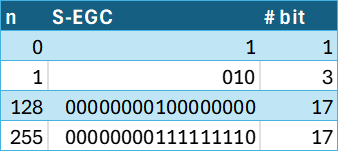   

Le immagini create ad hoc estremizzano il concetto di direzionaità della predizione e i difetti della codifica Exp Golomb. Le immagini 'vStripes' e 'hStripes' sono la stessa figura, a meno di una rotazione di 90°. La loro entropia è 1 perché sono formate da pixel o bianchi o neri, in uguale quantità. Nel caso di 'hStripes' la predizione sbaglia solamente il primo pixel di ogni riga: la prima colonna è formata dagli errori 128 255 255 255... mentre il resto dell'immagine ha errore 0. Si ottiene infatti $bitrate = \frac{1\cdot17+255\cdot17+255\cdot256\cdot1}{256\cdot256} = 1,0625 \, bpp$. Per quanto riguarda 'vStripes' invece, la predizione sbaglia sempre e l'errore è costantemente 255 e per questo l'entropia dell'errore è bassa. Nonostante la bassa entropia, Exp Golomb usa molti bit per rappresentare il numero 255 e si ha $bitrate=\frac{1\cdot17+(256\cdot256-1)\cdot17}{256\cdot256}=17\,bpp$. Questo tasso è più del doppio di quello che occupa la rappresentazione binaria dei valori di grigio da 0 a 255 cioè 8 bpp.

Un discorso simile si può fare per le sfumature. In 'vShade' si hanno strisce orizzontali con lo stesso colore e quindi con errore di predizione nullo su tutta la riga.  $bitrate=\frac{1*17+255\cdot3+255\cdot256\cdot1}{256\cdot256}\approx 1.008026 \,bpp
$. In 'hShade' il colore cambia gradualmente in orizzontale producendo un errore costante di 1 (solo la prima colonna ha errore 255 per l'effetto di bordo) dunque $bitrate=\frac{1*17+255\cdot17+255\cdot256\cdot3}{256\cdot256}\approx 3.054687 \,bpp
$.  

Nei 4 casi precedenti il software zip riesce a individuare il pattern con cui è stata creata l'immagine, producendo una codifica estremamente migliore al tasso EG(Y). Si noti inoltre che Exp Golomb assegna sempre almeno un bit ad ogni pixel (e questo avviene se l'errore di predizione è 0) quindi anche un'immagine monocromatica avrebbe comunque un tasso di 1 bpp mentre zip riesce a sfruttare meglio questo tipo di pattern portando il tasso anche sensibilmente sotto a 1 bpp.

Infine 'noise' è generata in modo completamente randomico con distribuzione uniforme dei livelli di grigio, non ci sono quindi pattern sfruttabili da zip e nemmeno strisce orizzontali che rendano vantaggiosa la codifica predittiva semplice. La predizione è formata da pixel con una distribuzione di probabilità a triangolo, questo porta ad avere una certa quantità di pixel con errore "grande" che per la natura esponenziale di Exp Golomb porta ad avere una codifica particolarmente costosa.

In conclusione, il software zip si dimostra nettamente migliore nella codifica di immagini dotate di una certa regolarità mentre la codifica predittiva con Exp Golomb è tendenzialmente più efficace per le immagini 'reali'. 

## Parte 2

### 1. Effettuare la codifica predittiva “avanzata”: per prima cosa si costruisce il predittore p tramite una scansione dell’immagine *f*:

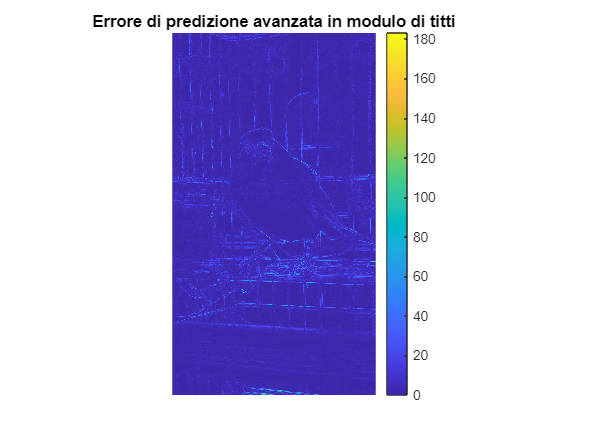

advPred = zeros(row, col, 'uint8');
% 1.1. Per ogni pixel dell%immagine in posizione n, m
for n = 1:row
    for m = 1:col
        % 1.2. Se è il primo pixel, il predittore è p(0,0) = 128
        if(n==1 && m==1) advPred(n,m) = 128;
        % 1.3. Altrimenti, se siamo sulla prima riga, 
        % il predittore è il pixel a sinistra di quello corrente
        elseif(n==1) advPred(n,m) = f(n, m-1); 
        % 1.4. Altrimenti, se siamo sulla prima colonna, 
        % il predittore è quello in alto
        elseif(m==1) advPred(n,m) = f(n-1, m);
        % 1.5. Altrimenti, se siamo sull'ultima colonna, 
        % il predittore è il valore mediano tra f(n−1,m), f(n,m−1), e f(n−1,m−1)
        elseif(m==col) advPred(n,m) = median([f(n-1, m), f(n, m-1), f(n-1, m-1)]);
        % 1.6. Altrimenti 
        % il predittore è il valore mediano tra f(n−1,m), f(n,m−1), e f(n−1,m+1)
        else advPred(n,m) = median([f(n-1, m), f(n, m-1), f(n-1, m+1)]);
        end
    end
end
% 1.7. Si calcola l'errore di predizione y = f − p (è un immagine)
advPredErr = double(f)-double(advPred); % differenza tra matrici

figure; imagesc(reshape(abs(advPredErr),row,col));  axis image; axis off; colorbar; title(sprintf('Errore di predizione avanzata in modulo di %s', imageName));
saveas(gcf, sprintf('%sAdvPredErr.png', imageName));

### 2. Valutare l'entropia di y

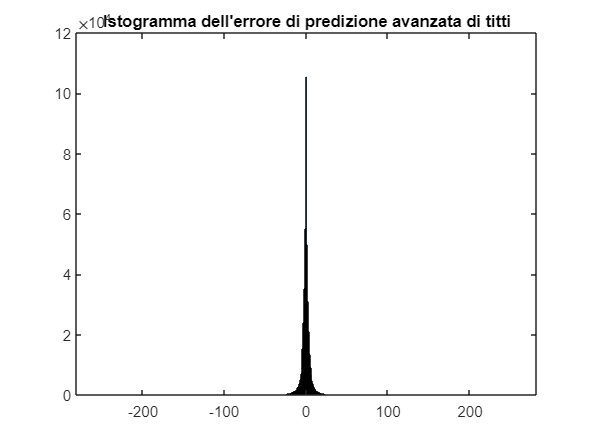

tmp = transpose(advPredErr);
rasterScan = tmp(:);
advHY = entropy(rasterScan);
histogram(rasterScan, -255:256); title(sprintf('Istogramma dell''errore di predizione avanzata di %s', imageName));
saveas(gcf, sprintf('%sAdvPredHist.png', imageName));

fprintf('L''entropia dell''errore di predizione avanzata per %s è HY = %5.4f bpp\n', imageName, advHY);

L'entropia dell'errore di predizione avanzata per titti è HY = 4.0577 bpp


### 3. Valutare il numero di bit necessari per codificare l’errore di predizione con la codifica Exp Golomb con segno, dedurne il tasso di codifica

bitCount = 0;
for n = 1:row
    for m = 1:col
        symbol = advPredErr(n,m);
        codeword = expGolombSigned(double(symbol));
        bitCount = bitCount + numel(codeword);
    end
end
advEG_bpp = bitCount/nPixel;
fprintf('Tasso di codifica S-EG su errore di predizione avanzata: %5.4f\n', advEG_bpp);

Tasso di codifica S-EG su errore di predizione avanzata: 4.4146


fprintf(['                                   |simple prediction| adv. prediction |\n' ... 
         'Immagine|  size  |  H(X)  | ZIP(X) |  H(Y)  |  EG(Y) |  H(Y)  |  EG(Y) |\n' ...
         '%8s| %dx%d|%7.4f |%7.4f |%7.4f |%7.4f |%7.4f |%7.4f |\n'], ... 
         imageName, row, col, HX, zip_bpp, simHY, simEG_bpp, advHY, advEG_bpp); 

                                   |simple prediction| adv. prediction |
Immagine|  size  |  H(X)  | ZIP(X) |  H(Y)  |  EG(Y) |  H(Y)  |  EG(Y) |
   titti| 885x498| 7.1834 | 5.2428 | 4.3854 | 4.7837 | 4.0577 | 4.4146 |


### 4. Confrontare l'entropia e il tasso di codifica predittiva avanzata con quelle del caso "semplice", con l'entropia dell'immagine e con il tasso di codifica dell'applicazione zip. Ripetere gli eseperimenti per più immagini e riportare i risultati. Commentare quanto trovato.

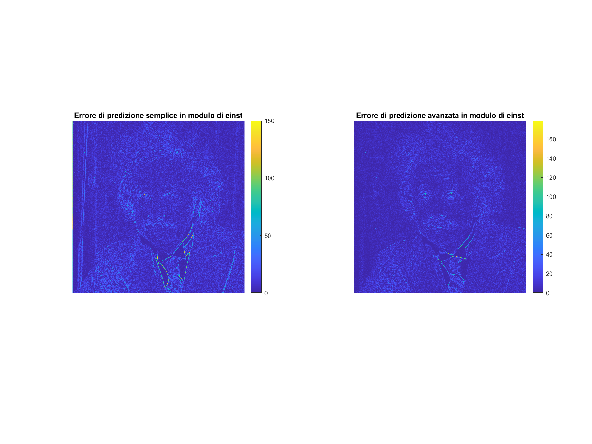

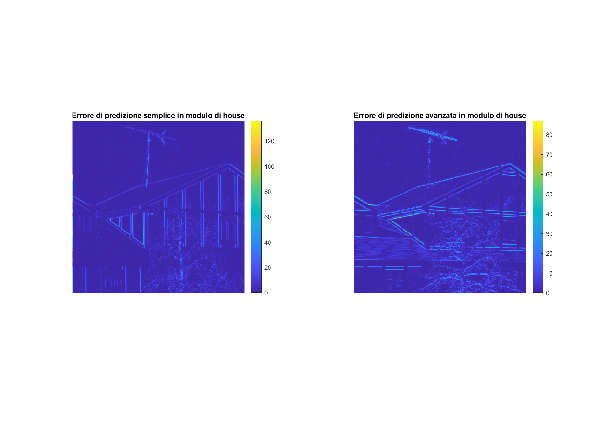

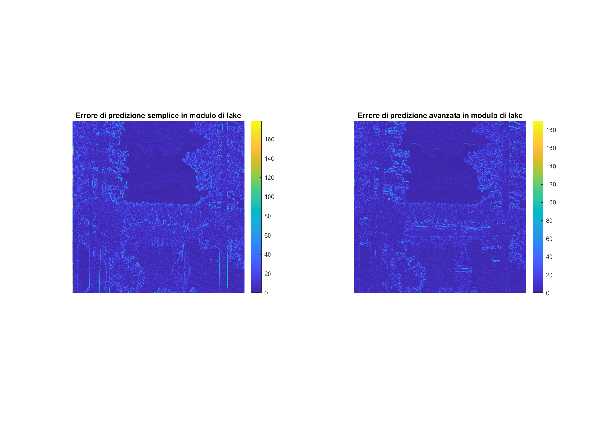

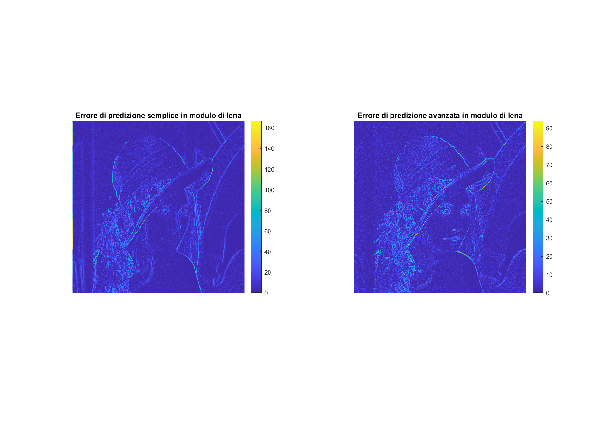

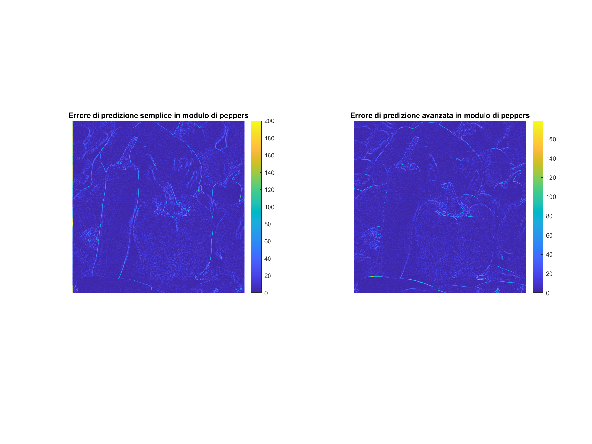

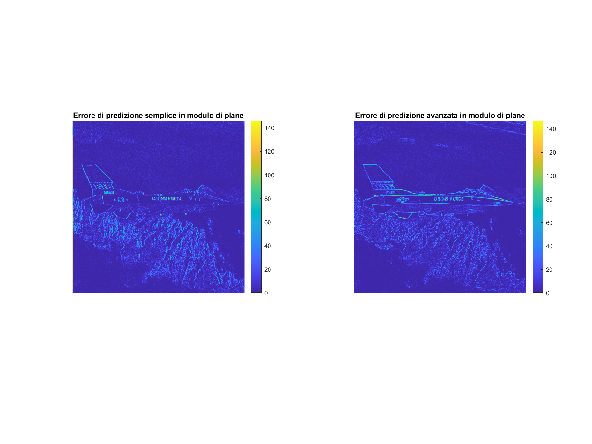

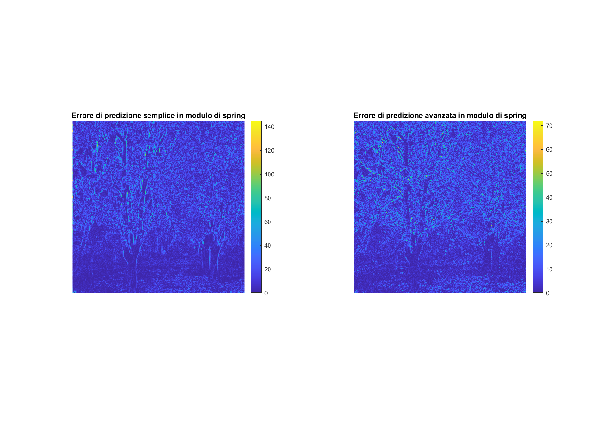

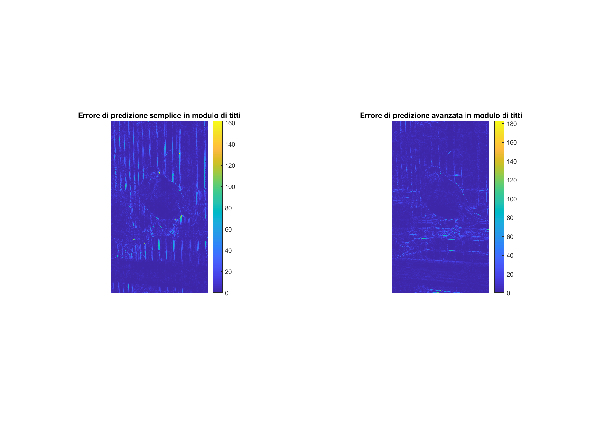

% mostro gli errori di predizione semplice e avanzata per ogni immagine
for i=1:numel(fileList)
    figure; tiledlayout(1,2,"TileSpacing", 'none', "Padding", 'none');
    nexttile; imshow(imread(sprintf("%sSimplePredErr.png", fileList{i})));
    nexttile; imshow(imread(sprintf("%sAdvPredErr.png", fileList{i})));
end

La codifica predittiva avanzata si è dimostrata migliore di quella semplice (anche se non di molto) in 10 delle 13 immagini provate. Nell'immagine 'house' la linearità del cielo ha fornito un buon risultato anche con la predizione semplice, caratteristica che non è stata sfruttata dalla predizione avanzata a causa della "ricombinazione" dei pixel. Nell'immagine 'hStripes' invece, la predizione avanzata porta ad errore nullo solamente nella prima riga (cioè dove si comporta come quella semplice) mentre tutto il resto dell'immagine ha errore 255. Da questo deriva la bassa entropia ma anche l'alto bitrate della codifica Exp Golomb. Un discorso analogo si può fare per 'vShade' dove le prestazioni peggiorano passando da codifica semplice ad avanzata. È interessante notare come utilizzando la predizione semplice ci sia un'enorme differenza tra 'vStripes' e 'hStripes' mentre con la predizione avanzata entrambe le immagini si comportano esattamente allo stesso modo ricadendo nel caso peggiore dell'errore di predizione, si perde quindi il vantaggio della direzionalità dell'immagine.

Per quanto riguarda le altre immagini, si nota che nella codifica avanzata l'errore di predizione avanzata è mediamente più basso rispetto a quello semplice. Nella rappresentazione dell'errore infatti, per la predizione semplice sono ben visibili i bordi, specialmente quelli verticali, mentre nella predizione avanzata sono molto meno marcati grazie all'azione dei pixel adiacenti. 

La codifica avanzata presenta un bitrate generalmente minore dell'entropia dell'immagine e, per quanto riguarda le immagini 'reali' anche migliore del tasso del file zip.

## Utilities

function result = entropy(values)
    occorrenze = hist(values,-255:256); % contiamo le occorrenze dei valori
    freqRel = occorrenze/sum(occorrenze); % Trasformiamo le occorrenze in frequenze relative
    p = freqRel(freqRel>0); %Rimuoviamo eventuali valori nulli di probabilità
    result = p*log2(1./p'); % formula dell'entropia. In Matlab "*" effettua il prodotto scalare
end

function bits= expGolombUnsigned(N)
    if N
        trailBits = dec2bin(N+1,floor(log2(N+1)));
        headBits = dec2bin(0,numel(trailBits)-1);
        bits = [headBits trailBits];
    else
        bits = '1';
    end
end

function bits= expGolombSigned(N)
    if N>0
        bits = expGolombUnsigned(2*N-1);
    else
        bits = expGolombUnsigned(-2*N);
    end
end
